## Convolution: why use orthogonal kernels for TF analysis? 

This live script visualizes the use of orthogonal kernels in analyses such as Hilbert transform, wavelet transforms, spctrograms and many more. 

1) Convolution: a simple mathematical function that quantifies the similarity between a pattern (a "kernel") such as the red square wave below with data (the blue rectangularish thingy below). The convolution (black line) reflects how similar the blue signal is with the kernel at any given time point. Convolution is thus used in all of digital signal processing. 

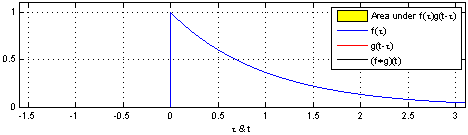

We start by redoing the signal and analysis used in convolution.mlx

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

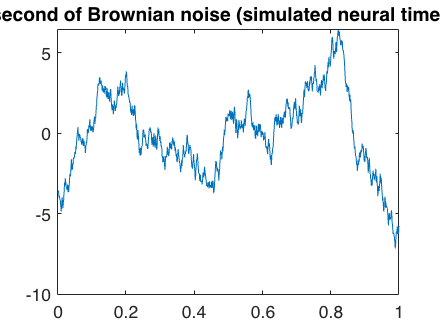

rng(080769) % set random number generator, for repproducibility
temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
brownsig = detrend(brownsig);
figure
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 

Now we make a simple signal, to be added to the brownian noise.

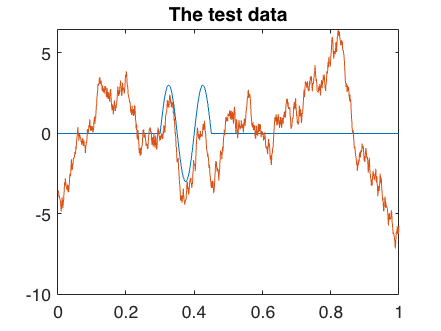

Sin10Hz = sin(2*pi*time*10).*3 ; % a 10 Hz sine wave with 3 µV amplitude
addsig = zeros(size(brownsig)); 
addsig(301:450) = Sin10Hz(301:450);
data1 = brownsig + addsig; 
plot(time, addsig), hold on
plot(time, data1); title('The test data') 

Now we need a kernel, let's take our added signal and see if we find it! 

kernel = Sin10Hz(301:450); 
kernlength = length(kernel)

kernlength = 150

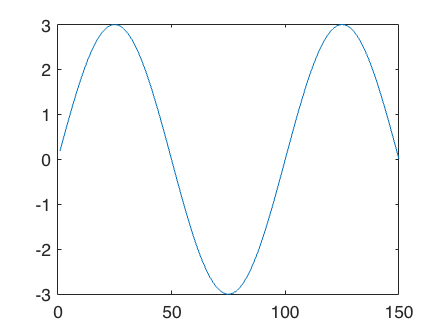

figure, plot(kernel)

Now the convolution. let's do it step by step again for this example, by using the dot product 

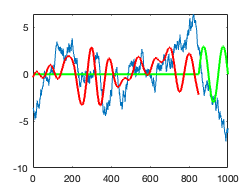



figure
for x = 1:size(data1,2)-kernlength
    convbyhand(x) = data1(x:x+kernlength-1)*kernel';
    plot(data1), hold on
    plot([zeros(1,x) kernel], 'g', 'LineWidth',2),  
    plot(convbyhand(1:x)./150, 'r', 'LineWidth',2), % divide by length of kernel to keep same scale
    pause(.01), hold off 
end

It looks like the convolution picks up phase information as much as it does amplitide information. This is good, but it means one kernel with one phase may not be enough. Let's add the orthogonal Kernel, a cosine! 

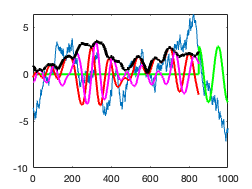

Cos10Hz = cos(2*pi*time*10).*3 ; % a 10 Hz cosine wave with 3 µV amplitude
kernel2 = Cos10Hz(301:450);

figure
for x = 1:size(data1,2)-kernlength
    convbyhand1(x) = data1(x:x+kernlength-1)*kernel';
    convbyhand2(x) = data1(x:x+kernlength-1)*kernel2';
    plot(data1), hold on
    plot([zeros(1,x) kernel2], 'g', 'LineWidth',2),  
    plot(convbyhand1(1:x)./150, 'r', 'LineWidth',2), % divide by length of kernel to keep same scale
    plot(convbyhand2(1:x)./150, 'm', 'LineWidth',2), % divide by length of kernel to keep same scale
    pause(.01), hold off 
end
hold on 
plot(abs(convbyhand2 + 1i*convbyhand1)./150, 'k', 'LineWidth',3)

There are many thing one could manipulate and illustrate now, but let's see what happens if I just increase the signal-to-noise ratio of the test signal (the sine wave embedded in the brownian noise)

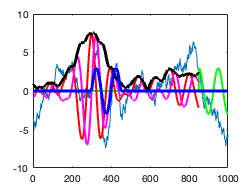

data2 = brownsig + addsig.*2; 

figure
for x = 1:size(data2,2)-kernlength
    convbyhand1(x) = data2(x:x+kernlength-1)*kernel';
    convbyhand2(x) = data2(x:x+kernlength-1)*kernel2';
    plot(data2), hold on
    plot([zeros(1,x) kernel2], 'g', 'LineWidth',2),  
    plot(convbyhand1(1:x)./150, 'r', 'LineWidth',2), % divide by length of kernel to keep same scale
    plot(convbyhand2(1:x)./150, 'm', 'LineWidth',2), % divide by length of kernel to keep same scale
    pause(.01), hold off 
end
hold on 
plot(abs(convbyhand2 + 1i*convbyhand1)./150, 'k', 'LineWidth',3)
plot(addsig, 'b', 'LineWidth',3)